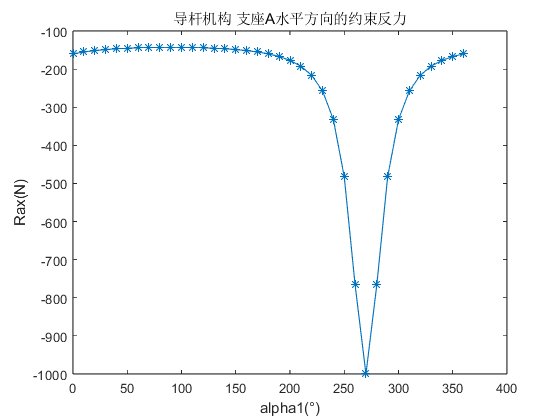

%定义l1杆的初始数据
l1 = 0.3;
alpha1 = 0:10:360;
omega1 = 5;
n = length(alpha1);

% 定义l2的初始数据
l2 = 0.8;
M3 = 100;
%机架长度
m = 0.4;

% 应加于曲柄1上的Mb
Mb = zeros(1,n);
% 支座A的约束力
Rax = zeros(1,n);
Ray = zeros(1,n);

% 移动副B的约束力
F = zeros(1,n);

% 支座C的约束力
Rcx = zeros(1,n);
Rcy = zeros(1,n);

for iterTime = 1:n
    
%     运动学分析

syms l22 alpha2   % l22指的是B、C之间的距离


% 矢量方程 m+l1=l22
% 沿x轴
q1 = l1*cosd(alpha1(iterTime))-l22*cosd(alpha2);
q2 = l1*sind(alpha1(iterTime))+m-l22*sind(alpha2);
%求解位移方程，得出 l22 alpha2
%采用迭代计算的方法，用前一时刻的位移来确定后一时刻的位移
if iterTime == 1
   x0 = [53,500];
end
T = vpasolve(q1,q2,x0);
l22 = T.l22;
alpha2 = T.alpha2;
   if iterTime > 1
   x0 = [alpha2,l22];
   end

   
%    对矢量方程求一阶导

syms v omega2
% 沿x轴
q3 = -l1*sind(alpha1(iterTime))*omega1-v*cosd(alpha2)+l22*sind(alpha2)*omega2;
% 沿y轴
q4 = l1*cosd(alpha1(iterTime))*omega1-v*sind(alpha2)-l22*cosd(alpha2)*omega2;


P = vpasolve(q3,q4);
v = P.v;
omega2 = P.omega2;

% 对矢量方程求二阶导

% 虚功率求解Mb
syms Mbb;
eq1 = Mbb*omega1-M3*omega2;
Mb(iterTime) = vpasolve(eq1);

% 隔离l2求解各约束反力
syms Rcxx Rcyy FF
% 对C点取矩
eq1 = -M3+FF*l22;
% 水平方向合力为0
eq2 = Rcxx-FF*sind(alpha2);
% 竖直方向合力为0
eq3 = Rcyy+FF*cosd(alpha2);


L = vpasolve(eq1,eq2,eq3);
Rcx(iterTime) = L.Rcxx;
Rcxx = L.Rcxx;
Rcy(iterTime) = L.Rcyy;
Rcyy = L.Rcyy;
F(iterTime) = L.FF;
FF = L.FF;


syms Rayy Raxx
% 对A点取矩
eq4 = Mbb-FF*l1*cosd(alpha1(iterTime)-alpha2);% 自动满足 无需计算
% 水平方向合力为0
eq5 = Raxx+FF*sind(alpha2);
% 竖直方向合力为0
eq6 = Rayy-FF*cosd(alpha2);


N = vpasolve(eq5,eq6);
Rax(iterTime) = N.Raxx;
Ray(iterTime) = N.Rayy;

end


figure(1)
plot(alpha1, Rax,'-*');
title('导杆机构 支座A水平方向的约束反力');
xlabel('alpha1(°)');
ylabel('Rax(N)');

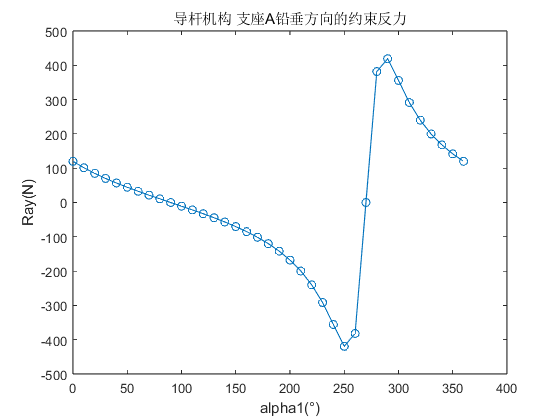



figure(2)
plot(alpha1, Ray,'-o');
title('导杆机构 支座A铅垂方向的约束反力');
xlabel('alpha1(°)');
ylabel('Ray(N)');

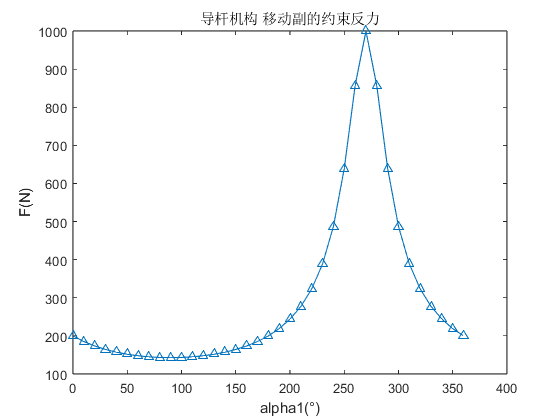


figure(3)
plot(alpha1, F,'-^');
title('导杆机构 移动副的约束反力');
xlabel('alpha1(°)');
ylabel('F(N)');

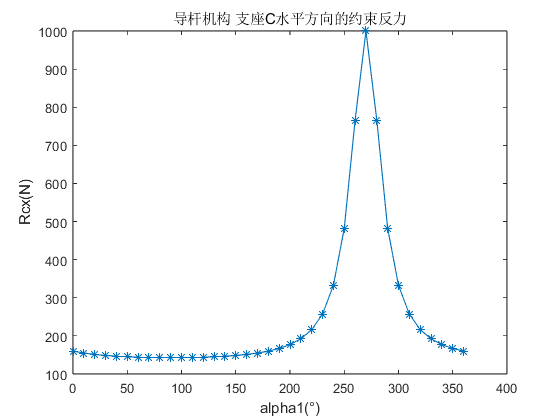


figure(4)
plot(alpha1, Rcx,'-*');
title('导杆机构 支座C水平方向的约束反力');
xlabel('alpha1(°)');
ylabel('Rcx(N)');

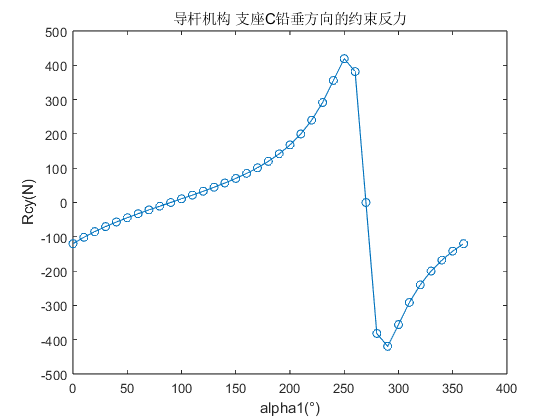



figure(5)
plot(alpha1, Rcy,'-o');
title('导杆机构 支座C铅垂方向的约束反力');
xlabel('alpha1(°)');
ylabel('Rcy(N)');

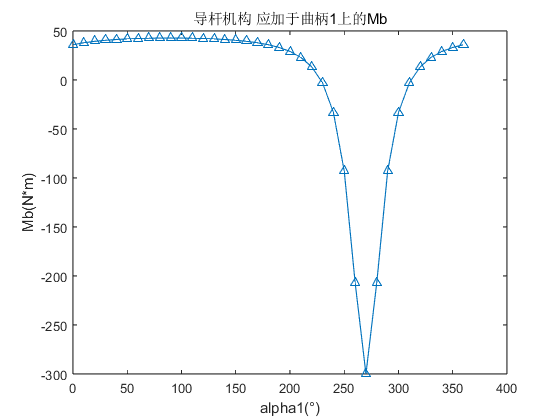


figure(6)
plot(alpha1, Mb,'-^');
title('导杆机构 应加于曲柄1上的Mb');
xlabel('alpha1(°)');
ylabel('Mb(N*m)');